% Define the data for lower limit, upper limit, and frequency
lowerLimits = [4,6,8,10,12,14,16,18,20,22,24,25,28]; 
upperLimits = [6,8,10,12,14,16,18,20,22,24,25,28,30]; 
frequencies = [2,5,4,11,11,11,13,10,7,6,4,3,1];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

         4             6            2    
         6             8            5    
         8            10            4    
        10            12           11    
        12            14           11    
        14            16           11    
        16            18           13    
        18            20           10    
        20            22            7    
        22            24            6    
        24            25            4    
        25            28            3    
        28            30            1    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 16.05


fprintf('Median: %.2f\n', medianValue);

Median: 16.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 17.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 5.45


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 15.90


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 1.10


fprintf('Karl: %.2f\n', Karl);

Karl: -0.17


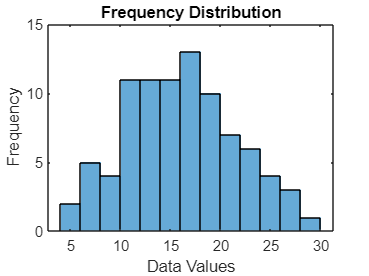


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');